# **Myoelectric control of isometric force**

**© **De Venuto Giuseppe, Tartarotti Michele 2022

**Objective:** In an experiment, the activity of N muscles of the upper limb is recorded while a subject applies forces at a fixed handle in different directions. The goal is to use muscle activity (electromyographic signals) to estimate the force exerted by the hand on the handle in real time and to analyze the spatial distribution of muscle activities (which muscles are activated in the various directions).

clc
clear
close all

## Load EMG data

The Dataset_isometric_task.mat file contains recorded activity of 8 muscles from the upper extremity: 

- Anterior Deltoid (aDEL)

- Posterior Deltoid (pDEL)

- Long head of Biceps (lBIC)

- Short head of Biceps (sBIC)

- Long head of Triceps (lTRI)

- Short head of Triceps (sTRI)

- Brachialis (BRA)

- Pectoralis Major (mPEC)

load Dataset_isometric_task.mat % load the dataset

The dataset is made up by a cell array Dataset.force.signals containing the force signals from the force sensor on the handle: on the same row there are 4 measurements of the same movement so that the different rows stand for different movements. Furthermore every cell of the cell array has two columns where in the first one there is the x component of force and in the second one the y component. In the Dataset.force structure we can also find the frequency at which the force is acquired.

Then there is another structure (Dataset.muscle) where there are the frequency at which the EMG signals are acquired and 8 cell arrays (one for each muscle) in which, as for the forces cell array, on same row there are the 4 repetitions of the same movement and the 12 rows stand for the different movement, but, unlike the previous case, now in every cell there is just one column.

labels = {
    'Anterior Deltoid (aDEL)';...
    'Posterior Deltoid (pDEL)';...
    'Long head of Biceps (lBIC)';...
    'Short head of Biceps (sBIC)';...
    'Long head of Triceps (lTRI)';...
    'Short head of Triceps (sTRI)';...
    'Brachialis (BRA)';...
    'Pectoralis Major (mPEC)'};  % define the cell array with the muscle names

To better manage the data we reorganized them into two different cell arrays and erased the signals from the Long head of Triceps (lTRI) since they were equal to the Short head of Triceps (sTRI) ones.

seg_mus=struct2cell(Dataset.muscle); % conversion of the EMG dataset from structure to cell
seg_for=struct2cell(Dataset.force); % conversion of the force dataset from structure to cell

seg_mus={seg_mus{1:4} seg_mus{6:end}}'; % redefine the seg_mus variable, without the Long head of Triceps (lTRI) muscle signals
labels={labels{1:4} labels{6:end}}'; % redefine the labels variable, without the Long head of Triceps (lTRI) muscle name

fc_seg_mus=seg_mus{end}; % EMG sample frequency
fc_seg_for=seg_for{end}; % force sample frequency

N_of_M = size(seg_mus,1)-1; % number of muscles
rig = 12; % number of movements
col = 4; % number of repetitions

for c=1:col
    for r=1:rig
        time_force{r,c}=(0:size(seg_for{1,1}{r,c},1)-1)/fc_seg_for; % define the time vectors needed for the plot of the forces over time
        time_emg{r,c}=(0:size(seg_mus{1,1}{r,c},1)-1)/fc_seg_mus; % define the time vectors needed for the plot of the EMG signals over time
    end
end

To obtain better results we had to preprocess the EMG signals both filtering them to remove the noise and working out their envelope through a moving average filter for the following analysis.

## Design of a band-pass Butterworth filter (IIR type)

1) Select filter parameters

low_range=35;
high_range=350;
filter_order = 10;

2) Calculate filter parameters

range = [low_range high_range]; % frequency range
bandwidth = fc_seg_mus/2; % half of sampling rate
[B,A]=butter(filter_order,range./bandwidth); % Design of Butterworth band-pass filter

## Design of envelope filter

Here we use a moving average filter. This is a FIR filter.

1) Specify time window in milliseconds

Twin=52;

2) Filter design

K = (Twin/1000)*fc_seg_mus;
Ba = ones(1,K)./K;
Aa = 1;

## Envelope estimation

mode = "MAV"; % Choice of the envelope estimation method

for ch=1:N_of_M
    for r=1:rig
        for c=1:col
            % find the filtered, the rectified signals and the envelope of the signals
            [sig_fil{ch,1}{r,c}, sig_ret{ch,1}{r,c}, env{ch,1}{r,c}]=filtering_and_envelope(r,c,ch,seg_mus,B,A,mode,Ba,Aa);

        end
    end
end

## Display EMG envelope over time

We plotted the envelope of just one repetition for the movements at 90, 180, 270 and 360 degrees.

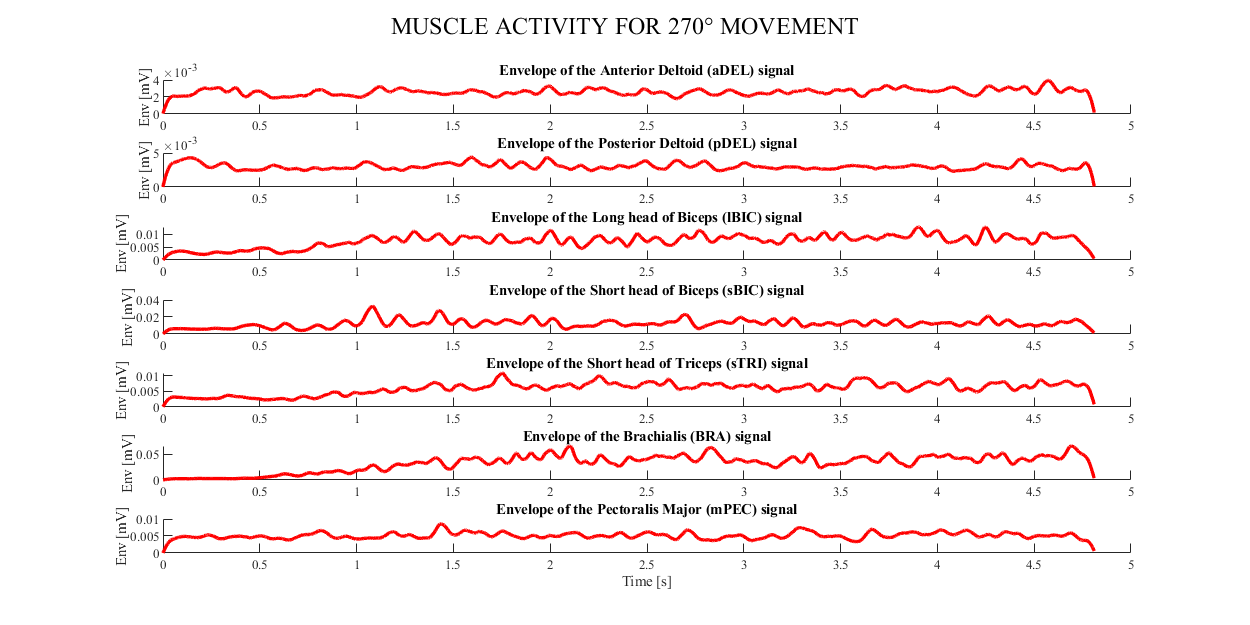

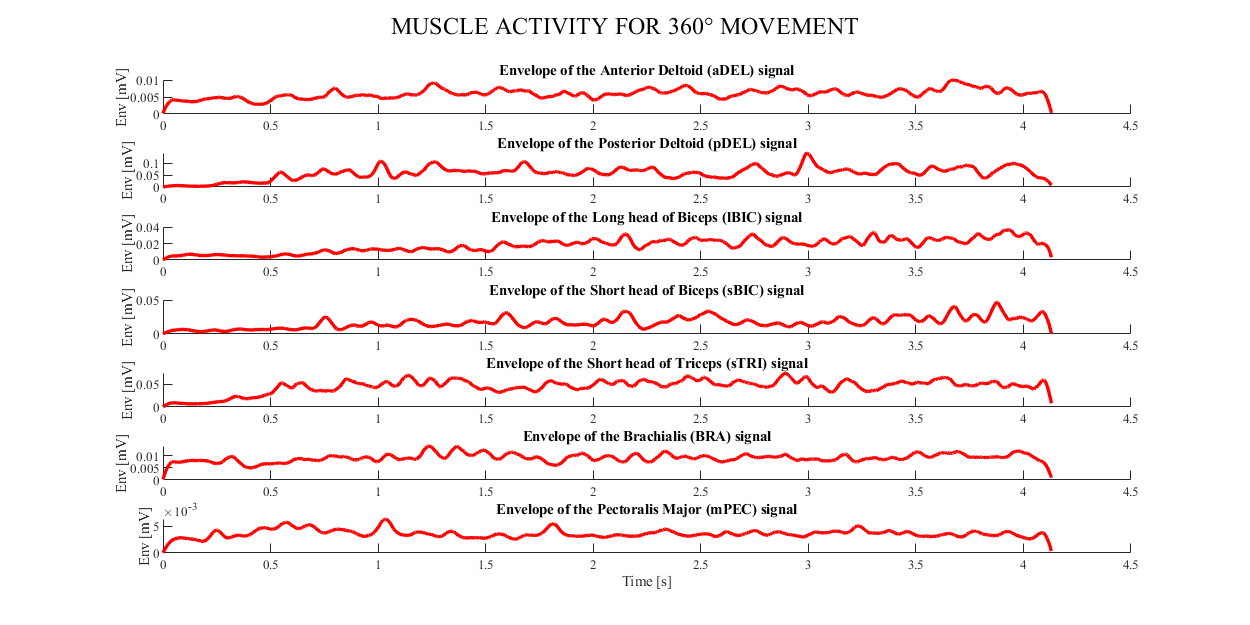

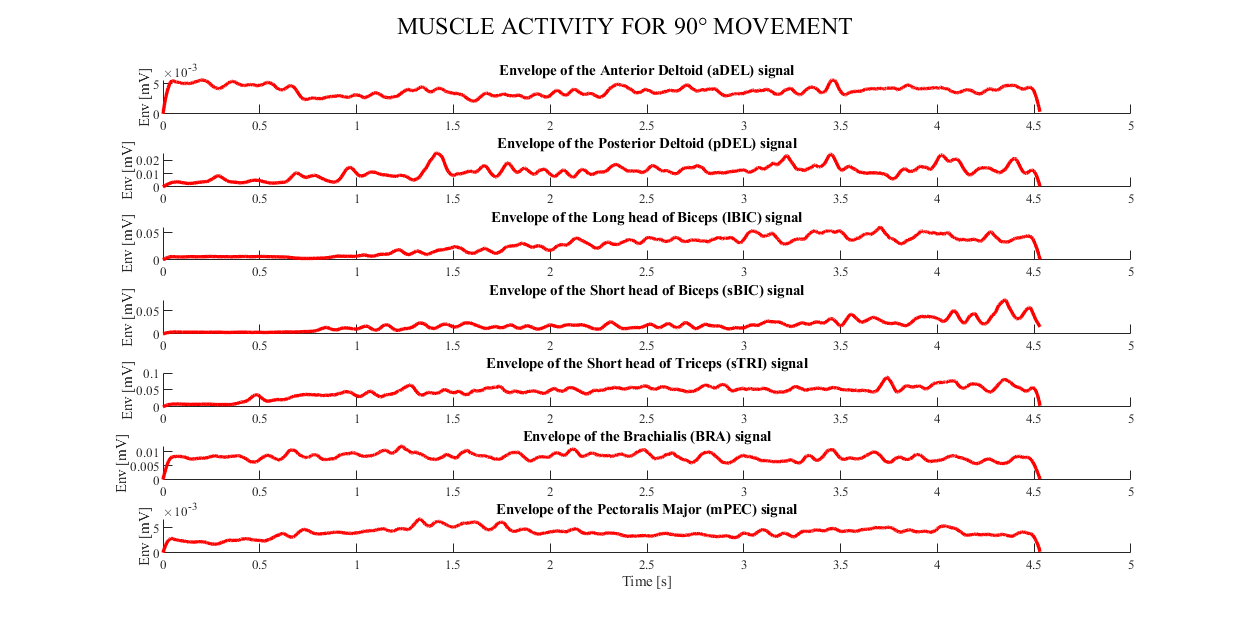

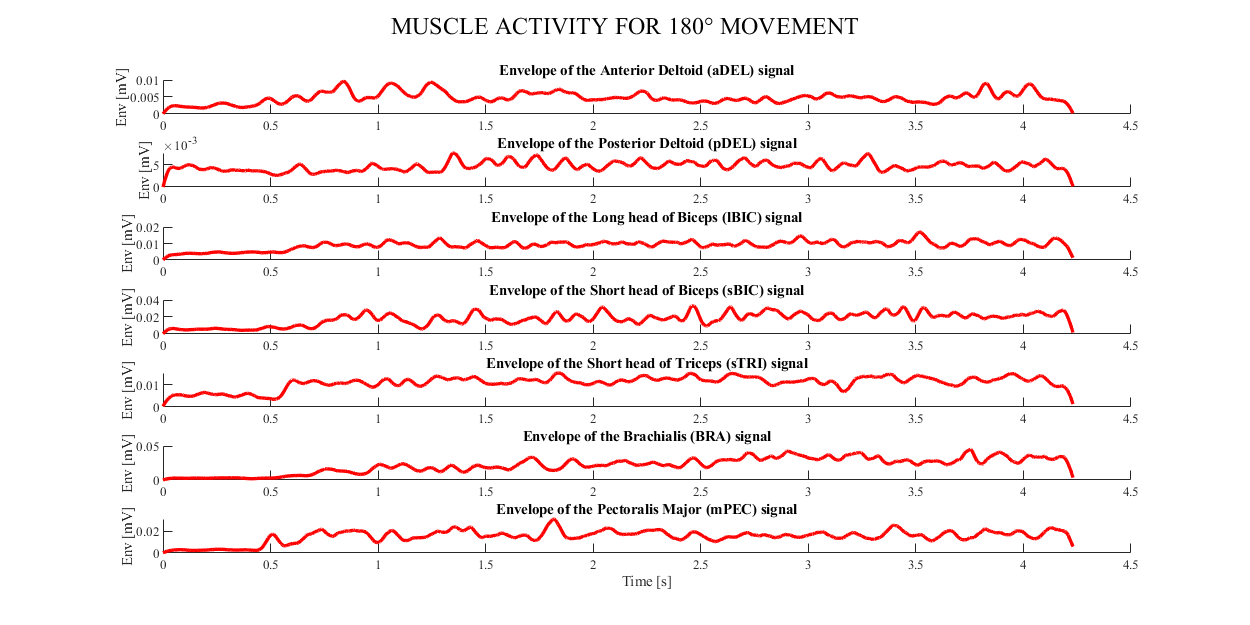

rig_plot_sig=4;
ang=[7/6*pi:pi/6:2*pi pi/6:pi/6:pi];
for r=1:rig_plot_sig
    figure
    for ch=1:N_of_M
        set(gcf,'pos',[100 100 1000 500])
        subplot (7,1,ch)
        line(time_emg{3*r,1},env{ch,1}{3*r,1},'col','r','linew',2)
        box off
        set(gca,'fontname','times')
    end

    for ch=1:N_of_M
        subplot(7,1,ch)
        title(sprintf('Envelope of the %s signal',labels{ch}))
        ylabel('Env [mV]')

    end

    subplot(7,1,1)
    subplot(7,1,7)
    xlabel('Time [s]')

    sgtitle(upper(sprintf('Muscle activity for %.0f° movement',ang(3*r)*180/pi)),'fontname','times')
end

To better understand the dataset we plotted for every repetition of every movement the direction of the forces and the trend of the magnitude of the force vectors over time.

## Display forces direction

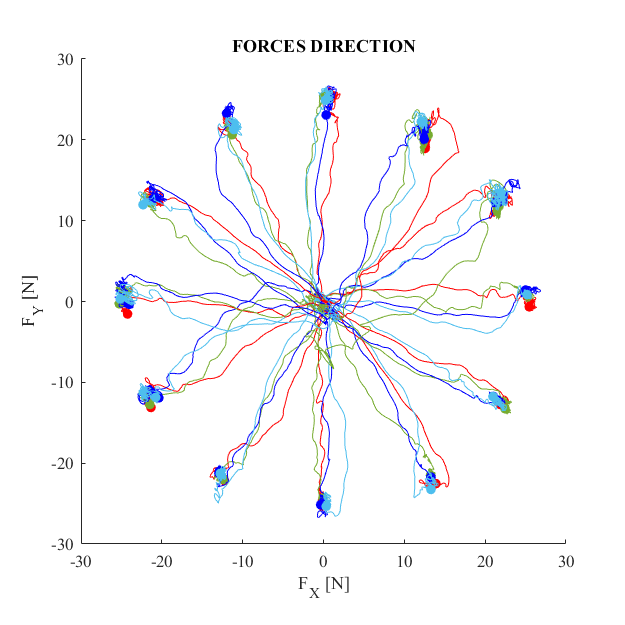

figure
set(gcf,'position',[100 100 500 500])
colrs={'r',[0.4660 0.6740 0.1880],'b',[0.3010 0.7450 0.9330],'g','k','r',[0.4660 0.6740 0.1880],'b',[0.3010 0.7450 0.9330],'g','k'};
for r=1:12
    for c=1:4
        plot(seg_for{1,1}{r,c}(:,1),seg_for{1,1}{r,c}(:,2),'Color',colrs{c})
        hold on
        plot(seg_for{1,1}{r,c}(end,1),seg_for{1,1}{r,c}(end,2),'marker','.','linestyle','none','MarkerSize',20,"Color",colrs{c})
    end
end
hold off
set(gca,'fontname','times')
axis square
xlabel('F_X [N]')
ylabel('F_Y [N]')
box off
title(upper('Forces direction'))
xlim([-30.0 30.0])
ylim([-30.0 30.0])

## Display forces magnitude over time

Thanks to the following plot we can figure out when the steady-state is reached and where performe the cut.

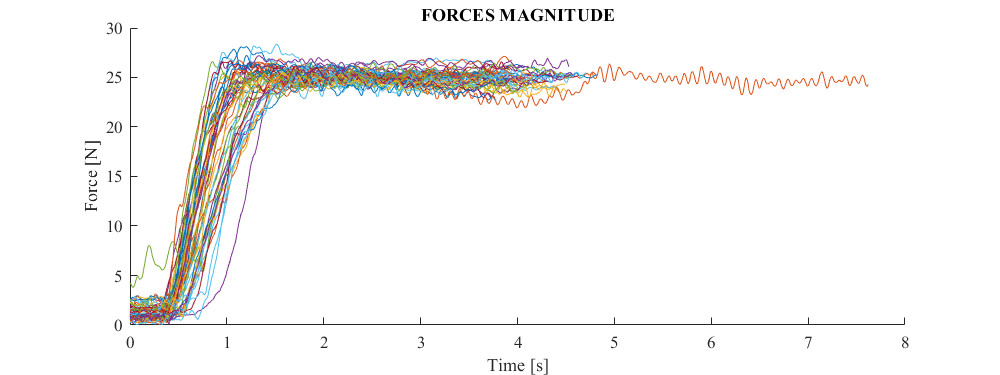

figure
set(gcf,'position',[100 100 800 300])
for r=1:12
    for c=1:4
        mod=sqrt(seg_for{1,1}{r,c}(:,1).^2+seg_for{1,1}{r,c}(:,2).^2);
        plot(time_force{r,c},mod)
        hold on
    end
end
hold off
set(gca,'fontname','times')
xlabel('Time [s]')
ylabel('Force [N]')
box off
title(upper('forces magnitude'))
xlim([0 8.0])
ylim([0 30.0])

## Cutting of the EMG envelope and force signals

To remove the irrelevant information from our signals we erased all the samples until the signals has reached a steady-state value. To do this we found the mean value of the magnitude for each vector of the forces taking into accunt only the signals samples after 2 seconds. Thus we performed the cut when the magnitude of each vector of the forces was equal or greater than 95% of its own mean value for the first time.

t_to_mean=2; % seconds from which the mean was performed
threshold_mean_force=t_to_mean*fc_seg_for; % force samples from which the mean was performed

for r=1:12
    for c=1:4
        % the mean value is found
        mm=mean(sqrt(seg_for{1,1}{r,c}(threshold_mean_force:end,1).^2+seg_for{1,1}{r,c}(threshold_mean_force:end,2).^2));
        % we found the indexes from which the cut of the force signals has to be done
        idx(r,c)=find(sqrt(seg_for{1,1}{r,c}(:,1).^2+seg_for{1,1}{r,c}(:,2).^2)>=0.95*mm, 1 );
    end
end

o_idx=idx*10-9; % indexes from which the EMG signals have to be cut

for k=1:N_of_M
    for r=1:rig
        for c=1:col
            o_env=[];
            o_env(:,:)=env{k,1}{r,c}(o_idx(r,c):end,:); % cutting of the EMG signals
            env_r{k,1}{r,c}=o_env(:,:);
        end
    end
end

for r=1:12
    for c=1:4
        o_seg_for=[];
        o_seg_for(:,:)=seg_for{1,1}{r,c}(idx(r,c):end,:); % cutting of the force signals
        seg_for_r{1,1}{r,c}=o_seg_for(:,:);
    end
end

## Display cut forces directions

Once we have done the cut we plotted the cut force signals 

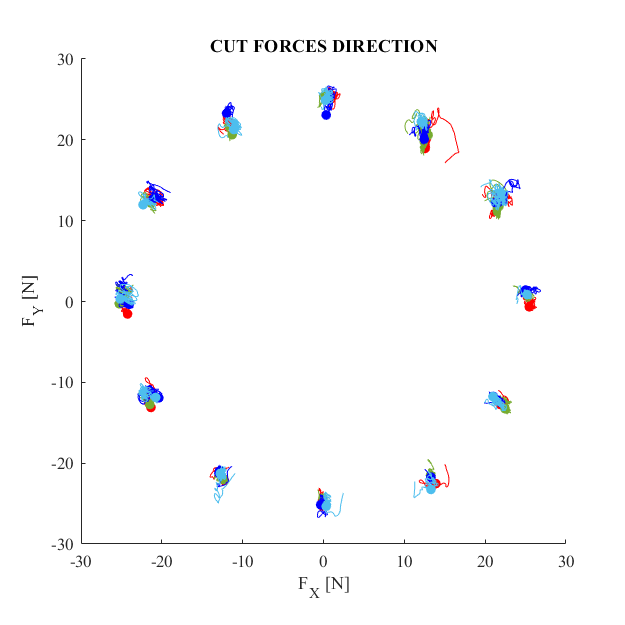

figure
set(gcf,'position',[100 100 500 500])
for r=1:12
    for c=1:4
        plot(seg_for_r{1,1}{r,c}(:,1),seg_for_r{1,1}{r,c}(:,2),'Color',colrs{c}) % plot of the cut forces
        hold on
        plot(seg_for_r{1,1}{r,c}(end,1),seg_for_r{1,1}{r,c}(end,2),'marker','.','linestyle','none','MarkerSize',20,"Color",colrs{c}) % plot the last point
        % of the force signals
    end
end
hold off
set(gca,'fontname','times')
axis square
xlabel('F_X [N]')
ylabel('F_Y [N]')
box off
title(upper('Cut forces direction'))
xlim([-30.0 30.0])
ylim([-30.0 30.0])

## Estimation of the mean envelope and the mean of the components of the force

Thus to reach our aim we chosed to get the mean of each cut envelope for each repetition of each movement for every muscle creating a new matrix 48x7 where on each column there is a different muscle and on each row there is a different repetition. Then we did the same with the forces components so that every 12 rows there is a repetition of the same movement both for the mean envelope matrix and for the vectors of the components of the forces. 

for ch=1:N_of_M
    for rep=1:rig*col
        mean_env_r(rep,ch)=mean(env_r{ch,1}{rep}(:)); % find the mean of each envelope over time
    end
end

for rep=1:rig*col
    mean_force_x(rep,1)=mean(seg_for_r{1,1}{rep}(:,1)); % find the mean of the mean of the x component of the forces over time

    mean_force_y(rep,1)=mean(seg_for_r{1,1}{rep}(:,2)); % find the mean of the mean of the y component of the forces over time
end

## Mean-Envelope Normalization 

For a better analysis of our data we chosed to normalize the data, dividing each column (each muscle) of the mean envelope matrix by the column's maximum value. The reason for such a thing lies in the fact that the absolute value of the EMG signals doesn't depend only on the muscle but also on the electrode and the electrode-skin interface.

for ch=1:N_of_M
    envelope(:,ch)=mean_env_r(:,ch)/max(mean_env_r(:,ch)); % normalization of the mean envelopes
end

## PCA estimation with Normalized Envelopes

We performend the PCA on the normalized mean envelopes to understand how they were made.

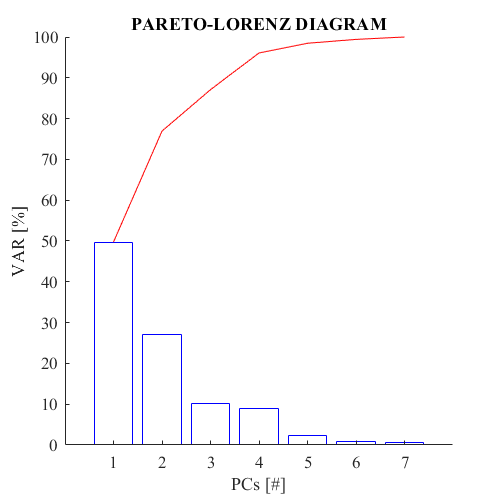

[U,X,S]=pca(envelope,"Economy",false);
figure
set(gcf,'position',[100 100 400 400])
bar(1:N_of_M,100*S./sum(S),"FaceColor","none","EdgeColor",'b')
hold on
plot(1:N_of_M,100*cumsum(S)./sum(S),'Color','r')
hold off
set(gca,'fontname','times')
xlabel('PCs [#]')
ylabel('VAR [%]');
box off
title(upper('Pareto-Lorenz Diagram'))
xlim([0 8])
ylim([0 100])

Then we displayed the dataset over the first two/three PCs to understand how it was made and it was possible to see how the movements in the same direction were represented by dots quite close to each other.

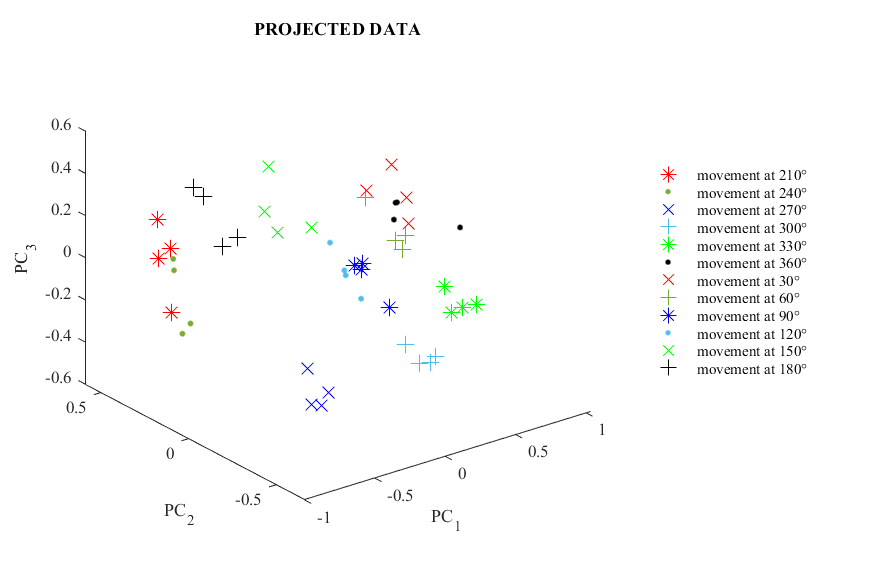

num_pc=3;

figure
set(gcf,'position',[100 100 700 450])
colrs={'r',[0.4660 0.6740 0.1880],'b',[0.3010 0.7450 0.9330],'g','k','r',[0.4660 0.6740 0.1880],'b',[0.3010 0.7450 0.9330],'g','k'};
markrs={'*','.','x','+','*','.','x','+','*','.','x','+'};

switch num_pc
    case 2
        for i=1:rig
            plot(X(i:12:end,1),X(i:12:end,2),'MarkerSize',10,'Color',colrs{i},"Marker",markrs{i},"LineStyle","none")
            leg{i}=sprintf('movement at %.0f°',ang(i)*180/pi);
            hold on
        end
        xlabel('PC_1')
        ylabel('PC_2')

    case 3
        for i=1:rig
            plot3(X(i:12:end,1),X(i:12:end,2),X(i:12:end,3),'MarkerSize',10,'Color',colrs{i},"Marker",markrs{i},"LineStyle","none")
            leg{i}=sprintf('movement at %.0f°',ang(i)*180/pi);
            hold on
        end
        xlabel('PC_1')
        ylabel('PC_2')
        zlabel('PC_3')
end

hold off
set(gca,'fontname','times')
legend(leg,'Location','eastoutside')
legend boxoff
box off
title(upper('projected data'))

## Multivariate Regression

Then we used the normalized mean envelope to perform the multivariate regression to find a model (a set of parameters) that could explain the relationship between the EMG signals and the direction of the forces. 

First of all we had to take into account that in a multivariate regression finding the model parameter means solving a linear system. For this reason, even if the 'fitlm' function put automatically to zero a certain number of variable to manage the regression, we imposed that the number of equations was greater than the number of unknows so that the system is never undetermined. Furthermore this condition is not applied just to the simplest multivariate regression with only first degree variables  (in our case the simple mean envelopes of the muscles i.e.$[e_1, e_2 ,..., e_7]$) but also to those with higher degree variables (e.g. $[e_1, e_2 ,..., e_7, e_1^2, e_2^2, ...,e_7^2,...,e_1^{n-1},e_2^{n-1},...,e_7^{n-1}, e_1^n, e_2^n, ... ,e_7^n]$).

Thus, to understand which degree of the variables was the best, we performed a LOOCV, both for the x and the y component of the forces, calculating the mse each time.

degree=1;
while size(envelope,1)-1>=(N_of_M*degree) % needed condition for the multivariate regression of the LOOCV

    % define the matrix of the variables to use for the multivariate regression of the LOOCV
    wip=[];
    for k=1:degree
        wip(:,end+1:end+N_of_M)=envelope.^k;
    end

    % performing the LOOCV
    for row=1:48

        X_to_regress=[wip(1:row-1,:);wip(row+1:end,:)];
        YX_to_regress=[mean_force_x(1:row-1);mean_force_x(row+1:end)];
        YY_to_regress=[mean_force_y(1:row-1);mean_force_y(row+1:end)];

        lm_x=fitlm(X_to_regress,YX_to_regress);
        p1=lm_x.Coefficients.Estimate(1:end,1);
        Y_pred_1=[1,wip(row,:)]*p1;
        MSE_1(row) =mse(Y_pred_1,mean_force_x(row)); % find the mse of the model for the x component

        lm_y=fitlm(X_to_regress,YY_to_regress);
        p2=lm_y.Coefficients.Estimate(1:end,1);
        Y_pred_2=[1,wip(row,:)]*p2;
        MSE_2(row) =mse(Y_pred_2,mean_force_y(row)); % find the mse of the model for the y component
    end
    M_MSE(degree,1:2)=[mean(MSE_1),mean(MSE_2)]; % find the overall mse for a particular degree of the variables for the multivariate regression
    degree=degree+1;
end

By means of the mse we found the degree of the variables for the multivariate regression that better explain the relationship between the EMG signals and the forces, and we plotted them on a semilogaritmic scale to better represent the minimum MSE value since the maximum one is in the order of thousands.

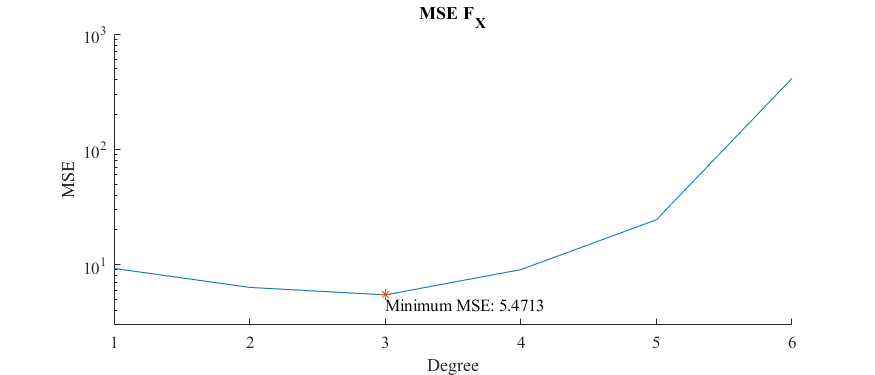

figure
set(gcf,'position',[100 100 700 300])
semilogy(M_MSE(:,1))
hold on
[minx, id_minx]=min(M_MSE(:,1));
set(gca,'fontname','times')
xlabel('Degree')
ylabel('MSE')
ylim([3 1000])
xticks(1:size(M_MSE,1))
plot(id_minx,minx,'*')
text(id_minx, minx-1,sprintf('Minimum MSE: %.4f',minx),'fontname','times')
title('MSE F_X')
box off

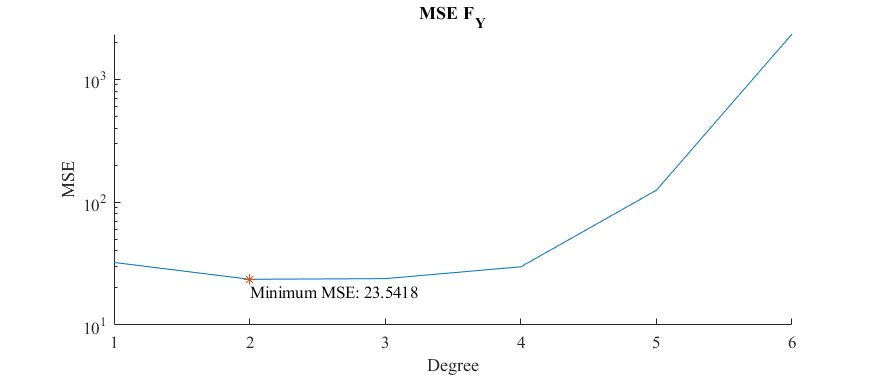

figure
set(gcf,'position',[100 100 700 300])
semilogy(M_MSE(:,2))
hold on
[miny, id_miny]=min(M_MSE(:,2));
set(gca,'fontname','times')
xlabel('Degree')
ylabel('MSE')
xticks(1:size(M_MSE,1))
plot(id_miny,miny,'*')
text(id_miny, miny-5,sprintf('Minimum MSE: %.4f',miny),'fontname','times')
title('MSE F_Y')
box off

## Forces estimation with the optimal degree of the variable for the multivariate regression

So we found that for the Fy the degree 2 leads to the best model while for the Fx the degree 3 is the best one. So we performed again the multivariate regression but this time taking into account all the available samples. 

DEGREE=max([id_minx, id_miny]);

WIP=[];

for k=1:DEGREE
    WIP(:,end+1:end+N_of_M)=envelope.^k;
end

YX_TO_REGRESS=mean_force_x;
YY_TO_REGRESS=mean_force_y;

% define the matrix to use to perform the multivariate regression for the F_x
% so it has also the second degree variables
X_TO_REGRESS_FOR_X=WIP(:,1:N_of_M*id_minx);

%define the matrix to use to perform the multivariate regression for the F_y
% so it has also the third degree variables
X_TO_REGRESS_FOR_Y=WIP(:,1:N_of_M*id_miny);

LM_X=fitlm(X_TO_REGRESS_FOR_X,YX_TO_REGRESS);
P1=LM_X.Coefficients.Estimate(1:end,1);
PRED_X=[ones(size(X_TO_REGRESS_FOR_X,1),1),X_TO_REGRESS_FOR_X]*P1;
MSE_X =mse(PRED_X,YX_TO_REGRESS);

LM_Y=fitlm(X_TO_REGRESS_FOR_Y,YY_TO_REGRESS);
P2=LM_Y.Coefficients.Estimate(1:end,1);
PRED_Y=[ones(size(X_TO_REGRESS_FOR_Y,1),1),X_TO_REGRESS_FOR_Y]*P2;
MSE_Y =mse(PRED_Y,YY_TO_REGRESS);

## Data-model comparison

With the following plots is possible to understand the quality of the optimal models. 

In a perfect model, in the first two plots, the dots should lie on the first quadrant bisector that would mean the perfect correspondance between the true and the predicted values since in the first one on the x axis there are the true values of the x component of the force and on the y axis the predicted ones.

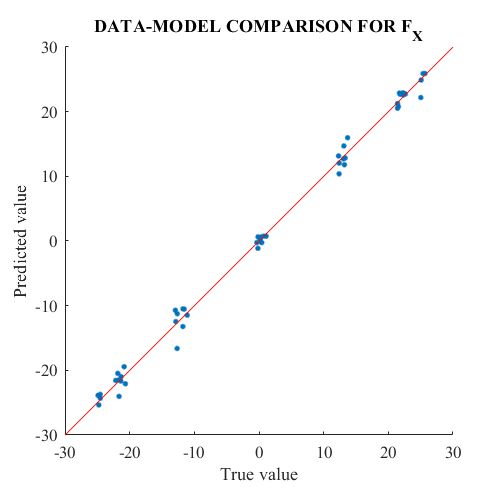

figure
set(gcf,'position',[100 100 400 400])
line(YX_TO_REGRESS,PRED_X,'linestyle','none','marker','.','MarkerSize',10)
hold on
plot([-30 30],[-30 30],'r')
set(gca,'fontname','times')
axis square
xlabel('True value')
ylabel('Predicted value')
title(upper('Data-model comparison for F_x'))
box off

While in the second one on the x axis there are the true values of the y component of the force and on the y axis the predicted ones.

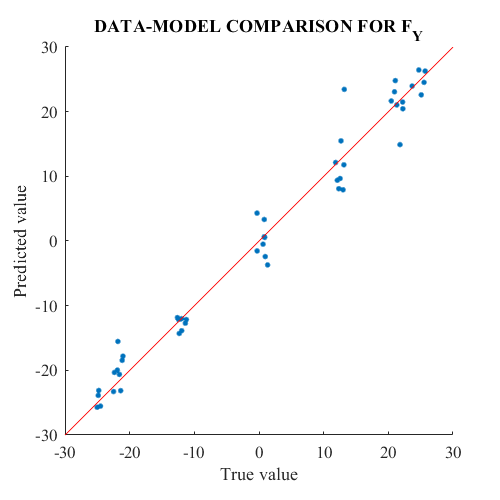

figure
set(gcf,'position',[100 100 400 400])
line(YY_TO_REGRESS,PRED_Y,'linestyle','none','marker','.','MarkerSize',10)
hold on
plot([-30 30],[-30 30],'r')
set(gca,'fontname','times')
axis square
xlabel('True value')
ylabel('Predicted value')
title(upper('Data-model comparison for F_y'))
box off

Then we plotted the true values of the forces direction and the predicted ones on the xy space to make a final overall comparison.

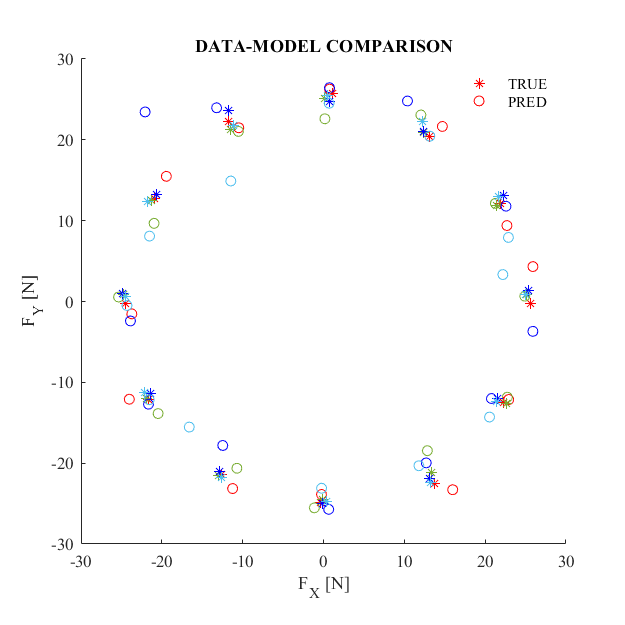

for k=1:4
    for i=1:12
        cols_2{1,(k-1)*12+i}=colrs{k};
    end
end

figure
set(gcf,'position',[100 100 500 500])
for i=1:48
    line(YX_TO_REGRESS(i),YY_TO_REGRESS(i),'marker','*','linestyle','none','Color',cols_2{i})
    hold on
    line(PRED_X(i),PRED_Y(i),'marker','o','linestyle','none','Color',cols_2{i})

end
hold off
set(gca,'fontname','times')
axis square
xlabel('F_X [N]')
ylabel('F_Y [N]')
box off
title(upper('Data-model comparison'))
xlim([-30.0 30.0])
ylim([-30.0 30.0])
legend({'TRUE','PRED'})
legend boxoff

## Distribution of the muscle activity

In the end we analysed the spatial distribution of the muscles activities making the mean of the envelope of the 4 repetitions in the same direction and making again the normalizzation. Then we found the different directions rounding the average direction of the 4 repetition on the same direction.

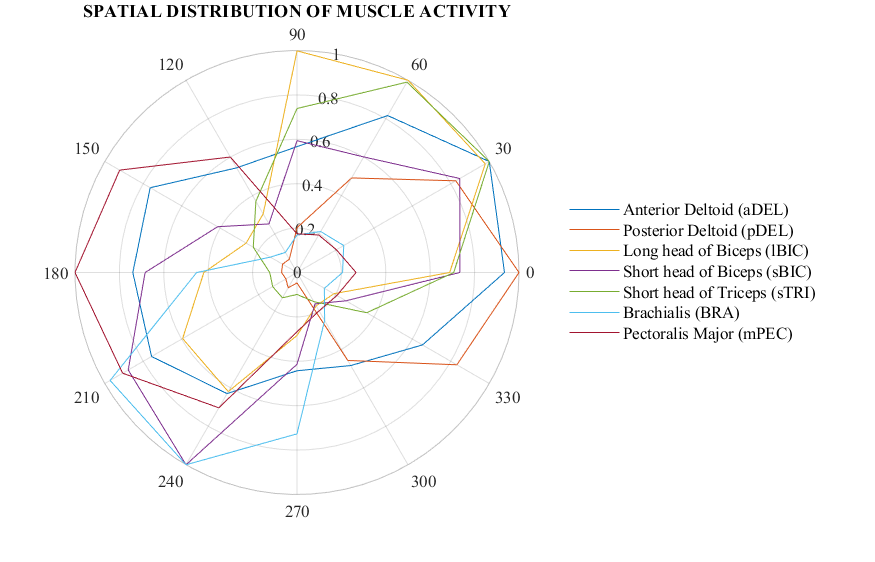

for i=1:12
    env_mov(i,:)=mean(envelope(i:12:end,:)); % find the mean of the mean envelopes of the 4 repetitions in the same direction
end

for ch=1:N_of_M
    env_mov(:,ch)=env_mov(:,ch)/max(env_mov(:,ch)); % make the normalization
end

for i=1:12
    for_mov_x(i,:)=mean(mean_force_x(i:12:end,:)); % find the mean of the mean x component forces of the 4 repetitions in the same direction

    for_mov_y(i,:)=mean(mean_force_y(i:12:end,:)); % find the mean of the mean y component forces of the 4 repetitions in the same direction
end

theta=round(atan2(for_mov_y,for_mov_x)/pi*6)*pi/6; % find the angles of the directions of the movements

figure
set(gcf,'position',[100 100 700 450])
for i=1:N_of_M
    polarplot([theta; theta(1)],[env_mov(:,i); env_mov(1,i)],'-')
    hold on
end
hold off
set(gca,'fontname','times')
legend (labels,"FontSize",10)
legend boxoff
title(upper('Spatial distribution of muscle activity'))

## Conclusion

From the results we can say that the multivariate regression has been critical to create a model to predict quite well the forces direction in spite of the very few available EMG signals. We have found that the best prediction of the two components of the forces is obtained using for the x component all the variables from the first to the third degree, i.e. $[e_1, e_2 ,..., e_7, e_1^2, e_2^2, ...,e_7^2, e_1^3, e_2^3, ... ,e_7^3]$, and for the y component all the variables from the first to the second degree, i.e. $[e_1, e_2 ,..., e_7, e_1^2, e_2^2, ...,e_7^2]$, where $e_n$ is the mean envelope of the n-th muscle. But despite this choice, we have found that the x component of the force is predicted much better than the other and a possible solution could be to have more data from more repetitions and/or more muscles useful for the multivariate regression.

Furthermore from the analysis of the spatial distribution of muscle activity we can say that the Pectoralis Major (mPEC) is active mainly for movement in a range between 120° and 240° while the Brachialis(BRA) is active mainly between 180° and 270°.

On the other hand we can find the Posterior Deltoid (pDEL) which is active mainly for movement in a range between 300° and 60° and the Short head of Triceps (sTRI) that is active mainly between 0° and 90° .

On the remaining three muscles we can say that they are active both between 300° and 90°, and between 120° and 270°, but just the activity of the Anterior Deltoid (aDEL) is the same in both the directions, since the Short head of Biceps (sBIC) is more active between 150° and 270° than between 330° and 90° while the Long head of Biceps (lBIC) behaves in the opposite way.

So, in the end we can claim that every muscle is mainly specialized in the movement in a particular range of directions exept for the aDEL that is active almost in every one, and some of them operate in synergy to exert a force in a particular direction.